# 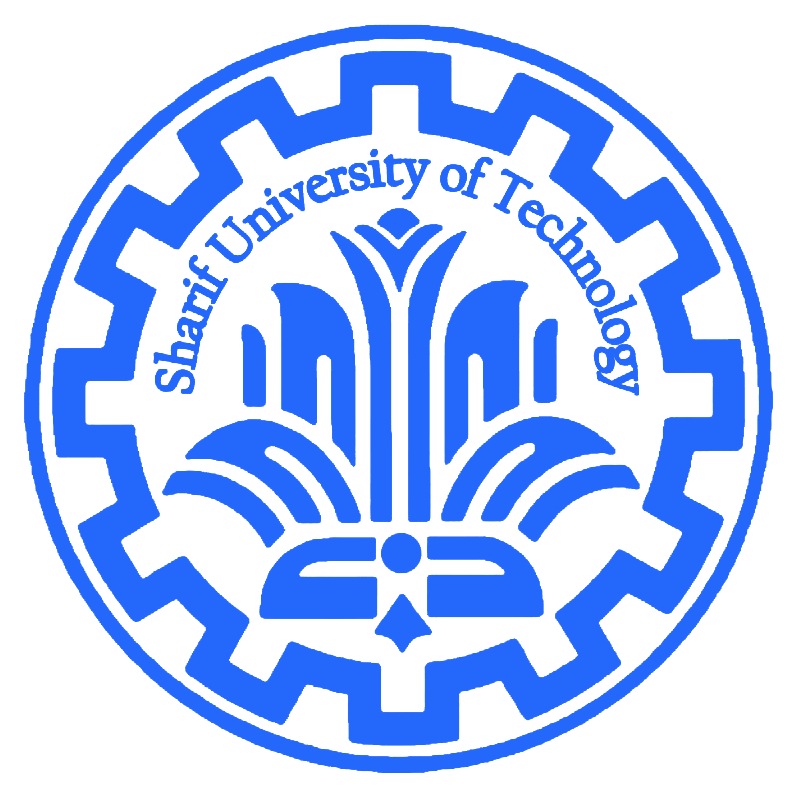

# 
$$\textbf{Stochastic Processes}
$$


# 
$$\text{Computer Assignment \#2
}
$$


#### 
$$\textit{Masoud Tahmasbi Fard - 402200275
}$$


### 
$$\textbf{Question \#3}$$


**............................................................................................................**

### 
$$\text{Part A}.$$
 

.............................................................................................................

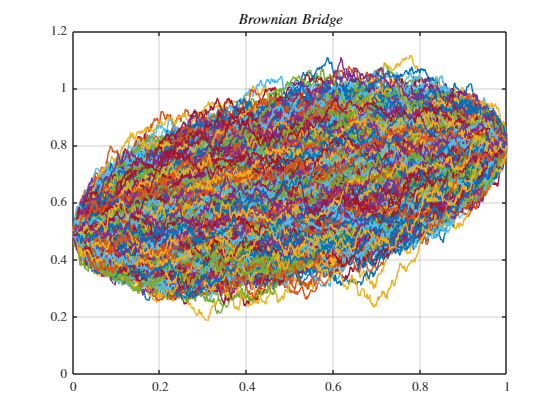

a = 0.5;
b = 0.8;
T = 1;
sigma = 0.2;
n_sample = 1000;
n_trajectories = 10000;
t = linspace(0,T,n_sample);
dt = diff(t(1:2)); 
X_all = zeros(n_trajectories,n_sample);

for j = 1:n_trajectories
    X = zeros(n_sample,1);
    X(1) = a;
    X(n_sample) = b;
    for i = 1: (n_sample - 2)
        X(i+1) = X(i) + ((b - X(i))/(T - t(i)))*dt + sigma*sqrt(dt)*randn(1,1);
    end
    X_all(j,:) = X;
end

figure
plot(t,X_all)
ax = gca;
xaxisproperties= get(ax, 'XAxis');
xaxisproperties.TickLabelInterpreter = 'latex'; 
yaxisproperties= get(ax, 'YAxis');
yaxisproperties.TickLabelInterpreter = 'latex';   
ax.XAxis.FontSize = 10;
title('$Brownian\;Bridge$','interpreter','latex')
grid on;

### 
$$\text{Part B}.$$
 

.............................................................................................................

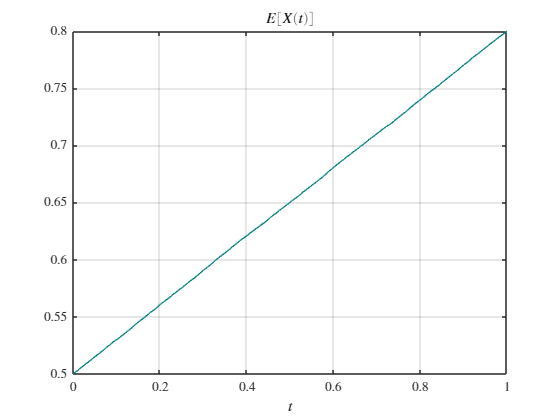

mean_t = mean(X_all,1);
var_t = var(X_all,0,1);

figure
plot(t,mean_t,'Color','#008080')
ax = gca;
xaxisproperties= get(ax, 'XAxis');
xaxisproperties.TickLabelInterpreter = 'latex'; 
yaxisproperties= get(ax, 'YAxis');
yaxisproperties.TickLabelInterpreter = 'latex';   
ax.XAxis.FontSize = 10;
title('$E[X(t)]$','interpreter','latex')
xlabel("$t$",'interpreter','latex')
grid on;

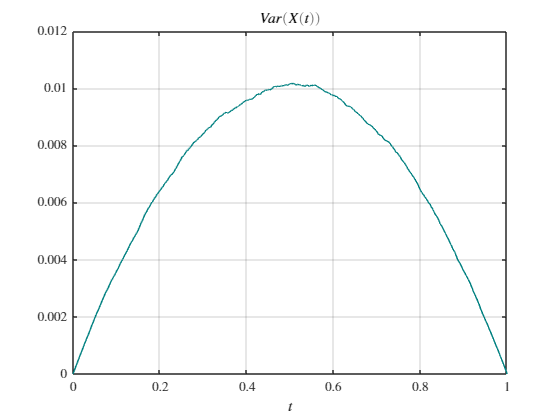

figure
plot(t,var_t,'Color','#008080')
ax = gca;
xaxisproperties= get(ax, 'XAxis');
xaxisproperties.TickLabelInterpreter = 'latex'; 
yaxisproperties= get(ax, 'YAxis');
yaxisproperties.TickLabelInterpreter = 'latex';   
ax.XAxis.FontSize = 10;
title('$Var(X(t))$','interpreter','latex')
xlabel("$t$",'interpreter','latex')
grid on;